clc; clear all;
A=[ 0       , 1, 0, 0;
    16.0976 , 0, 0, 0;
    0       , 0, 0, 1;
    -0.73177, 0, 0, 0]

A =          0    1.0000         0         0
   16.0976         0         0         0
         0         0         0    1.0000
   -0.7318         0         0         0



B=[ 0;
    -0.1463;
    0;
    0.0976]

B =          0
   -0.1463
         0
    0.0976



C=[ 1, 0, 0, 0;
    0, 0, 1, 0]

C =      1     0     0     0
     0     0     1     0



D=0

D = 0

X0=[0;
    0;
    0;
    0];

E2=gerarMatrizControbilidade(A,B)

E2 =          0   -0.1463         0   -2.3551
   -0.1463         0   -2.3551         0
         0    0.0976         0    0.1071
    0.0976         0    0.1071         0


controlavel(E2)

ans = logical
   1


T=gerarMatrizDeTransposcaoCanonicaControladora(E2,A)

T =          0         0   -0.1463         0
         0         0         0   -0.1463
   -1.4641         0    0.0976         0
         0   -1.4641         0    0.0976


[Ac,Bc,Cc]=aplicarTranformacaodeSimiliraridade(A,B,C,T)

Ac =          0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
         0         0   16.0976         0


Bc =          0
    0.0000
         0
    1.0000


Cc =          0         0   -0.1463         0
   -1.4641         0    0.0976         0



Q=C'*C

Q =      1     0     0     0
     0     0     0     0
     0     0     1     0
     0     0     0     0


R=1

R = 1

K=lqr(A,B,Q,R)

K =  -244.7533  -61.2266   -1.0000   -5.1889


[P,L,K]=care(A,B,Q,R)

P = 	1.0e+03 *

    7.4681    1.8743    0.0612    0.3019
    1.8743    0.4705    0.0158    0.0780
    0.0612    0.0158    0.0052    0.0135
    0.3019    0.0780    0.0135    0.0637


L =   -0.2133 + 0.2132i
  -0.2133 - 0.2132i
  -4.0122 + 0.0183i
  -4.0122 - 0.0183i


K =  -244.7533  -61.2266   -1.0000   -5.1889


Ac=A-B*K

Ac =          0    1.0000         0         0
  -19.7098   -8.9574   -0.1463   -0.7591
         0         0         0    1.0000
   23.1562    5.9757    0.0976    0.5064


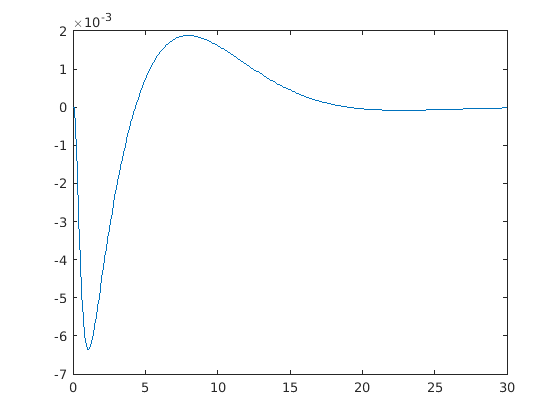

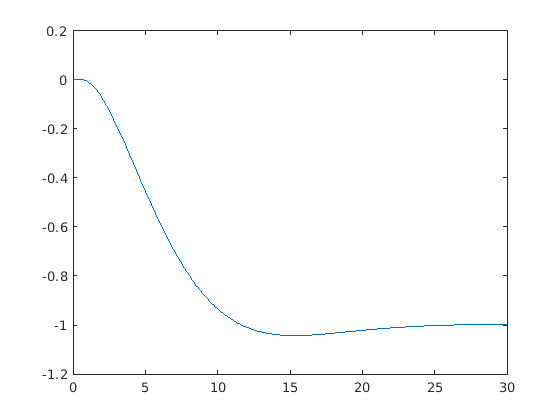

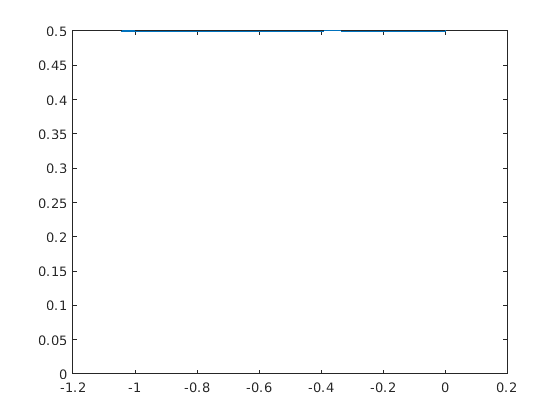

closeLoop=ss(Ac,B,C,0);
dt=0.1;
t = 0:dt:30;  % 201 points
u = (t>0);

[yOut,tOut]=lsim(closeLoop,u,t,X0);
plotGraficos(tOut,yOut)

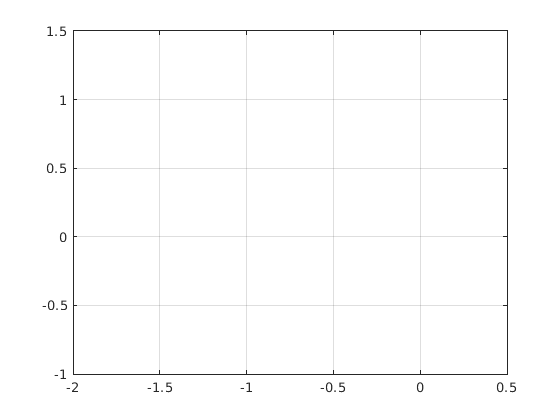

grid on

    %anim(i)=getframe;

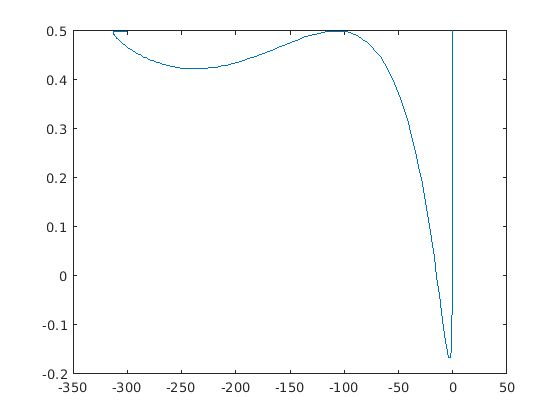

function E=gerarMatrizControbilidade(A,B)

for i=1:size(A)
    E(:,i)=A^(i-1)*B;
end
end

function out=controlavel(E)
if rank(E)==size(E)
    out=true;
else
    out=false;
end
end

function T=gerarMatrizDeTransposcaoCanonicaControladora(E,A)
inver=inv(E);
sizeM=size(E);
sizeM=sizeM(1,1);
p=inver(sizeM,:);

for i=1:size(E)
    T(i,:)=p*A^(i-1);
end
T=inv(T);
end

function [An,Bn,Cn]=aplicarTranformacaodeSimiliraridade(A,B,C,T)
    An=inv(T)*A*T;
    Bn=inv(T)*B;
    Cn=C*T;
end

function plotGraficos(t,y)
    xCard=y(:,2);
    yCard=0;
    xPen=xCard+0.5*sin(y(:,1));
    yPen=0.5*cos(y(:,1));
    plot(t,y(:,1))
    figure
    plot(t,y(:,2))
    figure
    plot(xPen,yPen);
    hold on
    plot(xCard,yCard);
    figure
    i=1;
    for t=0:0.1:30
        plot(xPen(i),yPen(i));
        anim(i)=getframe();
        i=i+1;
    end
end